% Solution for (Introduction to) Speech Processing
% 
% Sheet 1
% 
% Authors: 
% Lukas Bombel (lukas.bombel@uni-oldenburg.de)
% Jonte Kriebel (jonte.kriebel@uni-oldenburg.de)
% ------------------------------------------------------------------
clc
clear
close all


## **Aufgabe A**

disp('---------------------------------')

---------------------------------


disp('Solution to Exercise 1.A:')

Solution to Exercise 1.A:


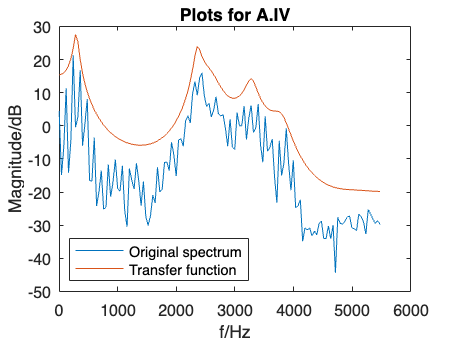


% (A.I)
% Read file and resample
[vSignal, iFs] = audioread('e.wav');
vSignal = resample(vSignal,11025,iFs);
iFs = 11025;


% (A.II) 
% cut 30 ms from signal and filter
vSignal = vSignal(1:round(iFs*0.025));
iFilterOrder = 15;
vLPC_coeff = lpc(vSignal, iFilterOrder);


% (A.III)
% Calculate impulse response with delta impulse
vDelta = zeros(size(vSignal));
vDelta(1) = 1;
h = filter(1,vLPC_coeff,vDelta); % or other way round


% (A.IV)
% calculate transfer function of impulse response
% and original spectrum

vMag = abs(fft(h));
vSpec = abs(fft(vSignal));
vFreq = 0:iFs/length(vSignal):iFs-iFs/length(vSignal);

% Plot both spectra
figure(1)
plot(vFreq(1:end/2),20*log10(vSpec(1:end/2)))
hold on
plot(vFreq(1:end/2),20*log10(vMag(1:end/2)))
hold off
title('Plots for A.IV')
xlabel('f/Hz')
legend(['Original spectrum'; 'Transfer function'], 'Location','southwest')
ylabel('Magnitude/dB')

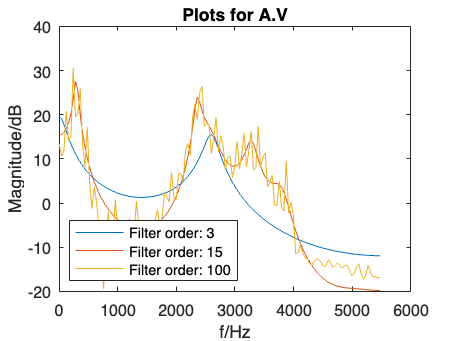



% (A.V)
% calculate new filters, impulse responses and transfer functions
iFilterOrderSmall = 3;
iFilterOrderLarge = 100;

vLPC_coeffSmall = lpc(vSignal, iFilterOrderSmall);
vLPC_coeffLarge = lpc(vSignal, iFilterOrderLarge);

hSmall = filter(1,vLPC_coeffSmall,vDelta); % or other way round
hLarge = filter(1,vLPC_coeffLarge,vDelta); % or other way round

vMagSmall = abs(fft(hSmall));
vMagLarge = abs(fft(hLarge));

% Plot all 3 transfer functions for different filter orders
figure(2)
plot(vFreq(1:end/2),20*log10(vMagSmall(1:end/2)))
hold on
plot(vFreq(1:end/2),20*log10(vMag(1:end/2)))
plot(vFreq(1:end/2),20*log10(vMagLarge(1:end/2)))
hold off
title('Plots for A.V')
xlabel('f/Hz')
sLegend = {['Filter order: ',num2str(iFilterOrderSmall)],...
    ['Filter order: ',num2str(iFilterOrder)],...
    ['Filter order: ',num2str(iFilterOrderLarge)]};
legend(sLegend, 'Location','southwest')
ylabel('Magnitude/dB')





% (A.VI)
% find all Peaks and read first two (check for plausibility)
[M, idx] = findpeaks(20*log10(vMag(1:end/2)));
iFormant1 = round(vFreq(idx(1)));
iFormant2 = round(vFreq(idx(2)));



% (A.VII)
% generate noise and filter with the coefficients
vNoise = randn(iFs,1);
hNoise = filter(1,vLPC_coeff,vNoise); % or other way round
% save generated data as audio, scale down to prevent clipping
audiowrite('noise.wav',hNoise/100,iFs);

## **Aufgabe B**

% (B.I & B.II)
disp('---------------------------------')

---------------------------------


disp('Solution to Exercise 1.B:')

Solution to Exercise 1.B:


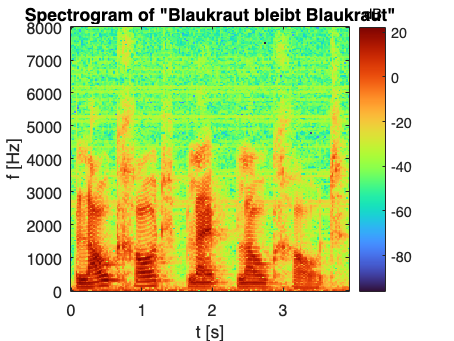


[vSignal, iFs] = audioread('blaukraut.wav');
vSignal = vSignal(:,1);
vSignal = resample(vSignal,16000,iFs);
iFs = 16000;

overlap = 0.5;
fBlockLength = 0.025;
fShift = fBlockLength*overlap;

[mOutput, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSignal,iFs,fBlockLength,fShift);

% apply hann window on blockwise signal
mOutput_windowed = zeros(iSamplesPerBlock,iNumBlocks);
for i = 1:iNumBlocks
    mOutput_windowed(:,i) = hanning(size(mOutput,1)) .* mOutput(:,i);
end


% (B.III)
mFFT = zeros(iSamplesPerBlock/2,iNumBlocks);
for i = 1:iNumBlocks
    vFFT = db(abs(fft(mOutput_windowed(:,i))));
    mFFT(:,i) = vFFT(1:end/2);
end

% (B.IV)
vFreq = 0:iFs/length(vSignal):iFs-iFs/length(vSignal);
vTime = 0:fBlockLength:iNumBlocks*fBlockLength;
image(vTime,vFreq(1:round(end/2)),mFFT, 'CDataMapping', 'scaled')
colormap('turbo')
hcb = colorbar();
hcb.Title.String = ('dB');
xlabel('t [s]')
ylabel('f [Hz]')
title('Spectrogram of "Blaukraut bleibt Blaukraut"')
axis xy

## Aufgabe C

% (C.I) to (C.IV)
disp('---------------------------------')

---------------------------------


disp('Solution to Exercise 1.C:')

Solution to Exercise 1.C:


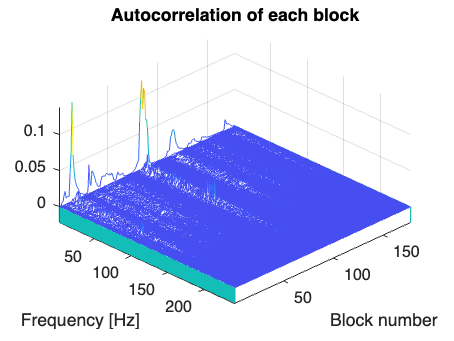


% read audio signal and resample
[vSentenceIn, iFs] = audioread('blaukraut.wav');
vSentenceIn = vSentenceIn(:,1);
vSentenceIn = resample(vSentenceIn,11025,iFs);
iFs = 11000;

% set parameters for blockwise processing
overlap = 0.5;
fBlockLength = 0.022;
fShift = fBlockLength*overlap;

[mOutput, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceIn,iFs,fBlockLength,fShift);

% apply hann window on blockwise signal
mOutput_windowed = zeros(iSamplesPerBlock,iNumBlocks);
for i = 1:iNumBlocks
    mOutput_windowed(:,i) = hanning(size(mOutput,1)) .* mOutput(:,i);
end

% set filter order
iFilterOrder = 15;

% preallocate matrix for filter-coefficients per block
mLPC = zeros(iFilterOrder+1,iNumBlocks);

% initiate error signal 
vEn = zeros(iSamplesMat,1);

% initiate noise vector
vNoise = randn(iSamplesMat,1)/100;

% initiate pulse train with wanted frequency
iPulseFreq = 300;
vPulse = zeros(iSamplesMat,1);
vPulse(1:round(iFs/iPulseFreq):end) = 0.05;

% preallocate signal vectors
vSentenceOut = zeros(iSamplesMat,1);
vSentenceOutNoise = zeros(iSamplesMat,1);
vSentenceOutPulse = zeros(iSamplesMat,1);

for i = 1:iNumBlocks
    % index for current block
    idx_start = (i-1)*iSamplesPerShift+1;
    idx_end = idx_start+iSamplesPerBlock-1;

    % calculate filter coefficients of block and save in matrix
    vLPC_coeff = lpc(mOutput_windowed(:,i), iFilterOrder);
    mLPC(:,i) = vLPC_coeff;
    
    % obtain exitation signal from filtering original signal block
    vEn_block = filter(vLPC_coeff,1,mOutput_windowed(:,i));

    mEn(:,i) = filter(vLPC_coeff,1,mOutput_windowed(:,i));
    
    vEn(idx_start:idx_end,1) = filter(vLPC_coeff,1,mOutput_windowed(:,i));
    
    % synthesize all signals 
    vSentenceOut(idx_start:idx_end) = filter(1,vLPC_coeff,vEn_block);
    vSentenceOutNoise(idx_start:idx_end) = filter(1,vLPC_coeff,vNoise(idx_start:idx_end));
    vSentenceOutPulse(idx_start:idx_end) = filter(1,vLPC_coeff,vPulse(idx_start:idx_end));
    
    vSentenceOutNoise(idx_start:idx_end) = hanning(iSamplesPerBlock) .* vSentenceOutNoise(idx_start:idx_end); 
    vSentenceOutPulse(idx_start:idx_end) = hanning(iSamplesPerBlock) .* vSentenceOutPulse(idx_start:idx_end);

    % write per block for spectrograms
    [mSentenceOut, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceOut, iFs, fBlockLength, fShift);
    [mSentenceOutNoise, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceOutNoise, iFs, fBlockLength, fShift);
    [mSentenceOutPulse, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceOutPulse, iFs, fBlockLength, fShift);
end


% calculate autocorrelation
for i = 1:iNumBlocks-1
    autocorrelation(:,i) = xcorr(mEn(:,i));
    %autocorrelation(:,i) = autocorrelation(:,i)/autocorrelation(242,i);
 end
zero_idx = ceil(size(autocorrelation,1)/2);

figure()
% freq_vec = 0:iSamplesPerBlock:iFs/(100*fBlockLength); % use linspace 
waterfall(autocorrelation(zero_idx:end,:))
view(135,45)
axis tight
set(gca,'XDir','reverse')
title('Autocorrelation of each block')
xlabel('Block number')
ylabel('Frequency [Hz]')
print('figures\waterfall_plot','-dpng')

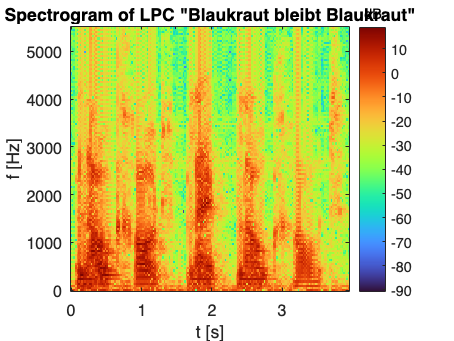



% save the three signals as audio 
audiowrite('sigout.wav',vSentenceOut,iFs);
audiowrite('sigoutnoise.wav',vSentenceOutNoise,iFs);
audiowrite('sigoutpulse.wav',vSentenceOutPulse,iFs);
%sound(vSentenceOutPulse,iFs)


% (C.V) spectrograms of:
% a) original sentence
mFFTSentenceOut = zeros(iSamplesPerBlock/2,iNumBlocks);
for i = 1:iNumBlocks
    vFFTSentenceOut = db(abs(fft(mSentenceOut(:,i))));
    mFFTSentenceOut(:,i) = vFFTSentenceOut(1:end/2);
end

vFreq = 0:iFs/length(vSignal):iFs-iFs/length(vSentenceOut);
vTime = 0:fBlockLength:iNumBlocks*fBlockLength;

figure()
image(vTime,vFreq(1:round(end/2)),mFFTSentenceOut, 'CDataMapping', 'scaled')
colormap('turbo')
hcb = colorbar();
hcb.Title.String = ('dB');
xlabel('t [s]')
ylabel('f [Hz]')
title('Spectrogram of LPC "Blaukraut bleibt Blaukraut"')
axis xy

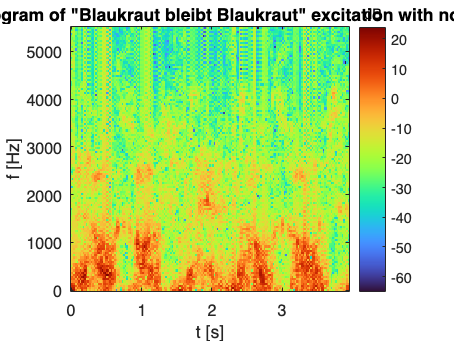


% b) sentence with noise excitation
mFFTSentenceOutNoise = zeros(ceil(iSamplesPerBlock/2),iNumBlocks);
for i = 1:iNumBlocks
    vFFTSentenceOutNoise = db(abs(fft(mSentenceOutNoise(:,i))));
    mFFTSentenceOutNoise(:,i) = vFFTSentenceOutNoise(1:end/2);
end

vFreq = 0:iFs/length(vSignal):iFs-iFs/length(vSentenceOutNoise);
vTime = 0:fBlockLength:iNumBlocks*fBlockLength;

figure()
image(vTime,vFreq(1:round(end/2)),mFFTSentenceOutNoise, 'CDataMapping', 'scaled')
colormap('turbo')
hcb = colorbar();
hcb.Title.String = ('dB');
xlabel('t [s]')
ylabel('f [Hz]')
title('Spectrogram of "Blaukraut bleibt Blaukraut" excitation with noise')
axis xy

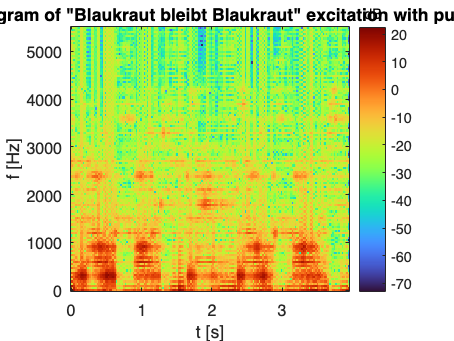


% c) sentence with pulse train excitation
mFFTSentenceOutPulse = zeros(iSamplesPerBlock/2,iNumBlocks);
for i = 1:iNumBlocks
    vFFTSentenceOutPulse = db(abs(fft(mSentenceOutPulse(:,i))));
    mFFTSentenceOutPulse(:,i) = vFFTSentenceOutPulse(1:end/2);
end

vFreq = 0:iFs/length(vSignal):iFs-iFs/length(vSentenceOutPulse);
vTime = 0:fBlockLength:iNumBlocks*fBlockLength;

figure()
image(vTime,vFreq(1:round(end/2)),mFFTSentenceOutPulse, 'CDataMapping', 'scaled')
colormap('turbo')
hcb = colorbar();
hcb.Title.String = ('dB');
xlabel('t [s]')
ylabel('f [Hz]')
title('Spectrogram of "Blaukraut bleibt Blaukraut" excitation with pulses')
axis xy